# **数学实验四**

   1.常见信贷方式：

A.**到期一次性还本息**，名义利率等于实际利率，客户在银行的定期存款就是这种方式。

B.**先按月还息，到期还本，**实际利率接近A的利率，是信用贷款常用的做法。

C.**等额本息法**，按月等额度还本金和利息，银行贷款的最常见方式。

D.**等额本金法**，按月等还本金，并还相应利息，银行房贷的次常见方式。

E.**借贷时先一次性扣除利息**，接下来每月还本金。

        A 君于本日向银行存入银行固定存款100万元，整存整取，期限2年，约定到期**自动转存**2年，且假设利率不变。银行当日转手将该款项贷给 B 君，期限为 10 年。

（1）请建立数学模型，描述 A 君和 B 君在该银行所设专项账户逐年余额情况。

（2）请建立数学模型，分别描述**A-E**5种情况下 B 君在该银行所设专项账户逐期余额情况。

（3）根据以上模型，比较 A-E 5 种情况下，存贷款的实际利率。

（4）讨论银行盈亏情况。

（5）如果利率允许波动(如LPR)，做合理假设，重新考虑以上问题。

请查阅银行最新存贷款利率

#### 解：(1)请建立数学模型，描述 A 君和 B 君在该银行所设专项账户逐年余额情况。

- **a）查阅资料：**查阅华夏银行的存款与贷款利率，得知2年期存款年利率r1=1.8%，5年期以上的贷款年利r2=3.95%。

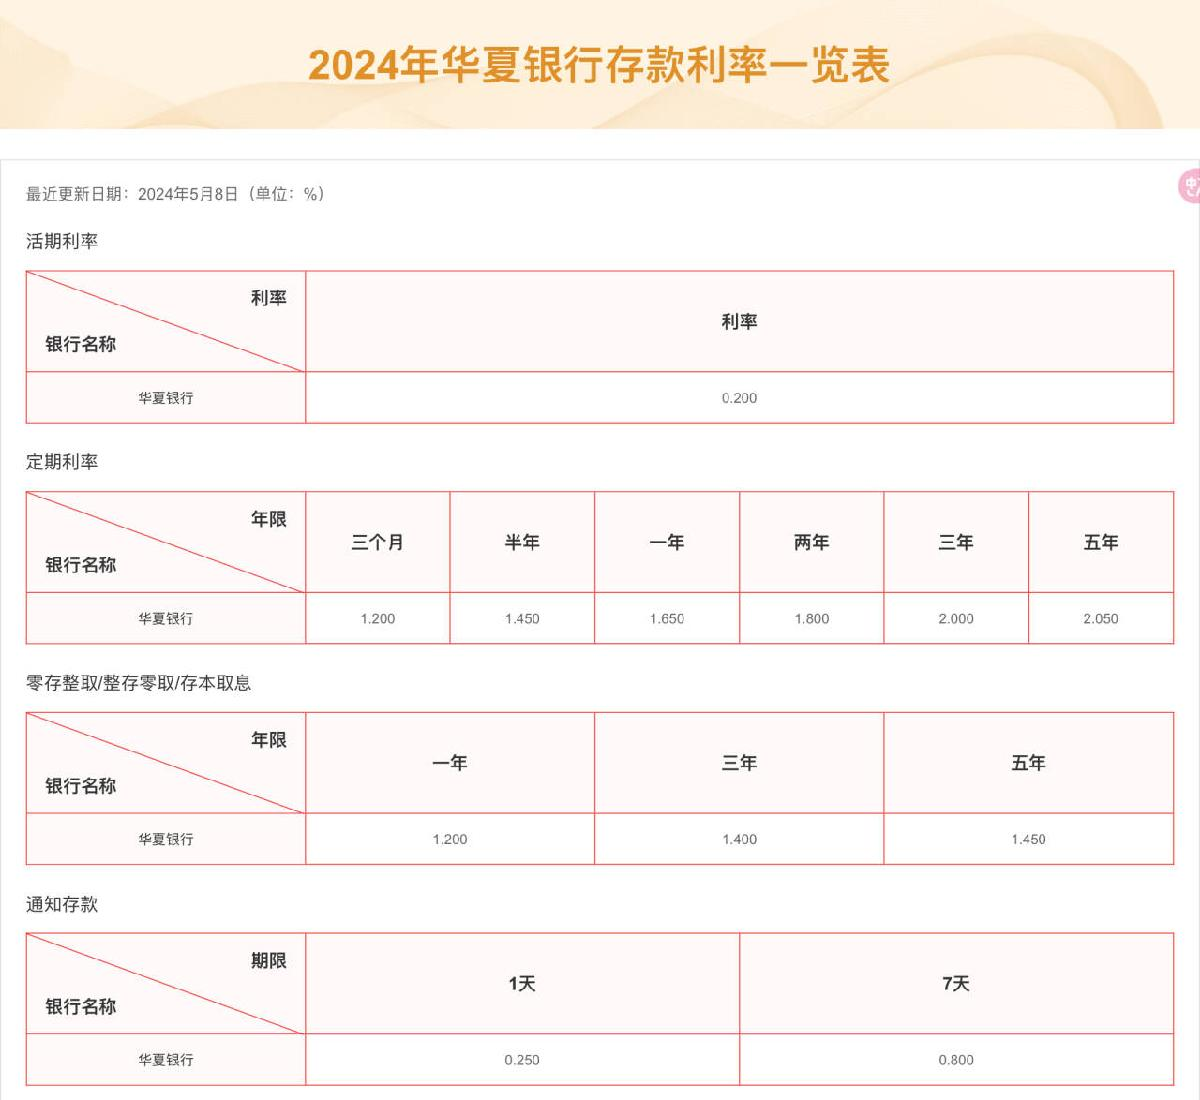

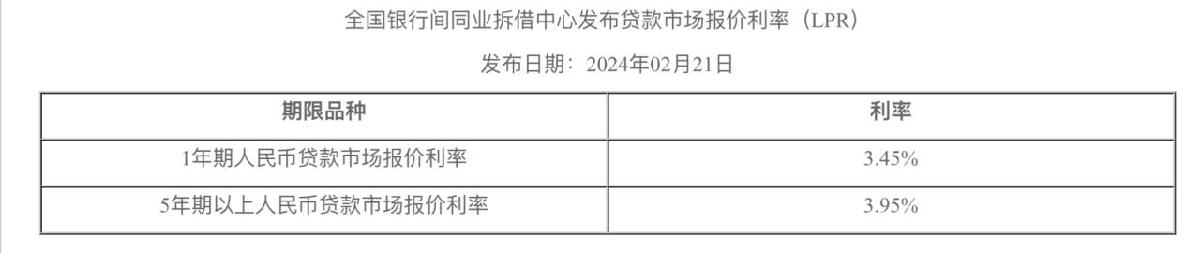

- **b）建立模型并求解：**

- A君账户模型——Ai为账户余额：$A_i=(1+r_1)A_{i-1},i=1,2,\cdots,5$，且A0=1000000，计算A君未来10年的账户余额。

% 设定时间单位为两年，则取时间单位长度为5
n = 5;
% 设定初始金额与利率
A0 = 1000000;
r1 = 0.018;
r11= r1*2;
% 初始化账户余额
A = zeros(n+1, 1);
A(1) = A0;
% 计算余额
for i = 1:n
    interest = A(i) * r11; % 计算利息
    A(i+1) = A(i) + interest; % 计算余额
end
% 转换为每年的余额情况
AA= zeros(n*2+1, 1);
AA(1)=A(1);
for i = 1:n
    AA(i*2)=A(i+1);
    AA(i*2+1)=A(i+1);
end

- 呈现A君未来10年的账户余额：

% 显示
years=0:1:10;
A_str = arrayfun(@(x) sprintf('%.0f', x), AA, 'UniformOutput', false);
T = table(years', A_str, 'VariableNames', {'年份', 'A君账户余额'});
disp(T);

    年份    A君账户余额 
    ____    ___________

      0     {'1000000'}
      1     {'1036000'}
      2     {'1036000'}
      3     {'1073296'}
      4     {'1073296'}
      5     {'1111935'}
      6     {'1111935'}
      7     {'1151964'}
      8     {'1151964'}
      9     {'1193435'}
     10     {'1193435'}



- 存储银行最后的支出：

PA=A(6);
save('P_fund.mat','PA','-append')

- 绘制图像呈现A君账户余额：

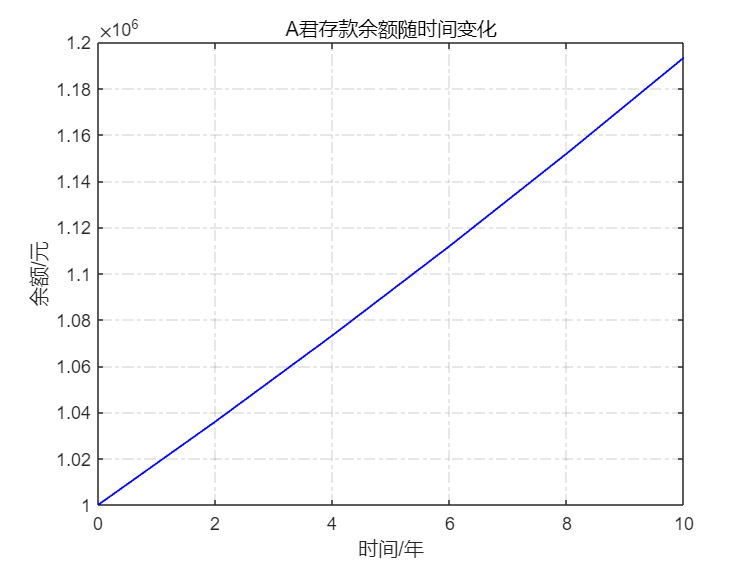

% 得到时间横轴
x=0:1:n;
x=x*2;
% 绘制余额随时间的变化
fig=plot(x, A,'b-');
% 设置线宽
fig(1).LineWidth =1.0;
% 打开网格
grid on;
set(gca, 'XGrid', 'on', 'YGrid', 'on', 'GridLineStyle', '-.');
% 设置坐标轴和标题
xlabel('时间/年');
ylabel('余额/元');
title('A君存款余额随时间变化');

-  B君账户模型（假设等额本息法）——Bk为账户余额：$B_k=(1+r_2)B_{k-1}-m,k=1,2,\cdots,120$，且B0=1000000，计算B君未来10年的账户余额。

clear;
% 设定时间单位为一月，则取时间单位长度为120
n = 10 * 12 ;
% 设定初始金额与利率
B0 = 1e6;
r2 = 0.0395;
r22 = r2 / 12;
% 计算每月还款额
m = r22*B0*(1+r22)^n / ((1+r22)^n - 1);
% 初始化余额数组
B = zeros(n+1, 1);
B(1) = B0;
% 计算余额
for i = 2:n+1
    B(i) = B(i-1)*(1+r22) - m; % 计算本月的余额
end
% 转换为逐年余额
x=0:1:10;
balance_year=zeros(11, 1);
for i=1:11
    balance_year(i)=B(12*(i-1)+1);
end

- 呈现B君未来10年的账户余额：

% 显示
years=0:1:10;
B_str = arrayfun(@(x) sprintf('%.0f', x), balance_year, 'UniformOutput', false);
T = table(years', B_str, 'VariableNames', {'年份', 'B君贷款余额'});
disp(T);

    年份    B君贷款余额 
    ____    ___________

      0     {'1000000'}
      1     {'916795' }
      2     {'830244' }
      3     {'740211' }
      4     {'646556' }
      5     {'549135' }
      6     {'447795' }
      7     {'342379' }
      8     {'232722' }
      9     {'118655' }
     10     {'0'      }



- 绘制图像呈现B君贷款余额：

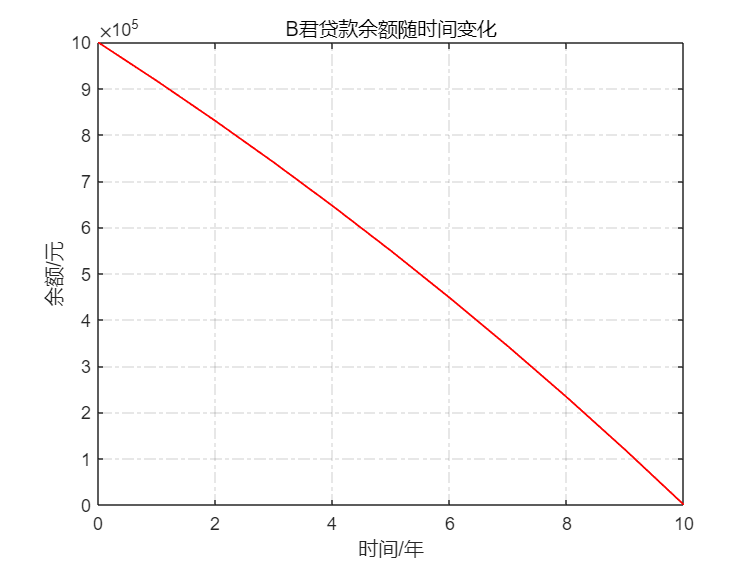

fig=plot(x, balance_year,'r-');
% 设置线宽
fig(1).LineWidth =1.0;
% 打开网格
grid on;
set(gca, 'XGrid', 'on', 'YGrid', 'on', 'GridLineStyle', '-.');
% 设置坐标轴和标题
xlabel('时间/年');
ylabel('余额/元');
title('B君贷款余额随时间变化');

####     (2)请建立数学模型，分别描述**A-E**5种情况下 B 君在该银行所设专项账户逐期余额情况。

- **a）方式A：到期一次性还本息**，名义利率等于实际利率，客户在银行的定期存款就是这种方式。

clear;
% 设置初值，计算总利息
B0 = 1e6;
r22 = 0.0395 *10;
interest=B0*r22;
% 计算账户余额
balance_year = zeros(11, 1)+B0;
balance_year(end)=0;

- 显示B君逐期余额情况：

years=0:1:10;
balance_str = arrayfun(@(x) sprintf('%.0f', x), balance_year, 'UniformOutput', false);
T = table(years', balance_str, 'VariableNames', {'年份', 'B君贷款余额（方式A）'});
disp(T);

    年份    B君贷款余额（方式A）
    ____    _________________

      0        {'1000000'}   
      1        {'1000000'}   
      2        {'1000000'}   
      3        {'1000000'}   
      4        {'1000000'}   
      5        {'1000000'}   
      6        {'1000000'}   
      7        {'1000000'}   
      8        {'1000000'}   
      9        {'1000000'}   
     10        {'0'      }   



- 存储银行最后的收入：

P1=balance_year(1)+interest;
save('P_fund.mat','P1','-append');

- 绘制图像呈现B君贷款余额：

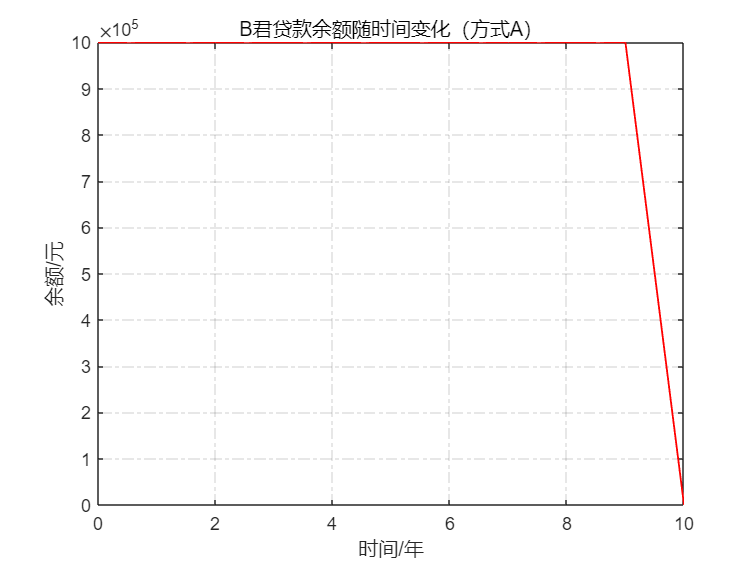

fig=plot(0:1:10, balance_year,'r-');
% 设置线宽
fig(1).LineWidth =1.0;
% 打开网格
grid on;
set(gca, 'XGrid', 'on', 'YGrid', 'on', 'GridLineStyle', '-.');
% 设置坐标轴和标题
xlabel('时间/年');
ylabel('余额/元');
title('B君贷款余额随时间变化（方式A）');

- **b）方式B：先按月还息，到期还本，**实际利率接近A的利率，是信用贷款常用的做法。

clear;
% 设定时间单位为两年为一月，则取时间单位长度为120
n=10*12;
% 设置初值，计算月利息
B0 = 1e6;
r2=0.0395;
r22 = r2 /12;
interest = zeros(n, 1);
% 计算账户余额
balance = zeros(n+1, 1)+B0;
balance(end)=0;

- 显示B君逐期余额情况：

months=0:1:n;
balance_str = arrayfun(@(x) sprintf('%.0f', x), balance, 'UniformOutput', false);
T = table(months', balance_str, 'VariableNames', {'月份', 'B君贷款余额（方式B）'});
disp(T);

    月份    B君贷款余额（方式B）
    ____    _________________

      0        {'1000000'}   
      1        {'1000000'}   
      2        {'1000000'}   
      3        {'1000000'}   
      4        {'1000000'}   
      5        {'1000000'}   
      6        {'1000000'}   
      7        {'1000000'}   
      8        {'1000000'}   
      9        {'1000000'}   
     10        {'1000000'}   
     11        {'1000000'}   
     12        {'1000000'}   
     13        {'1000000'}   
     14        {'1000000'}   
     15        {'1000000'}   
     16        {'1000000'}   
     17        {'1000000'}   
     18        {'1000000'}   
     19        {'1000000'}   
     20        {'1000000'}   
     21        {'1000000'}   
     22        {'1000000'}   
     23        {'1000000'}   
     24        {'1000000'}   
     25        {'1000000'}   
     26        {'1000000'}   
     27        {'1000000'}   
     28        {'1000000'}   
     29        {'1000000'}   
     30        {'1000000'}   
     31        {'

- 存储银行最后的收入：

P2=0;
for i=1:n
    interest(i)=B0*r22;
    P2=P2+interest(i);
end
P2=balance(1)+P2;
save('P_fund.mat','P2','-append');

- 绘制图像呈现B君贷款余额：

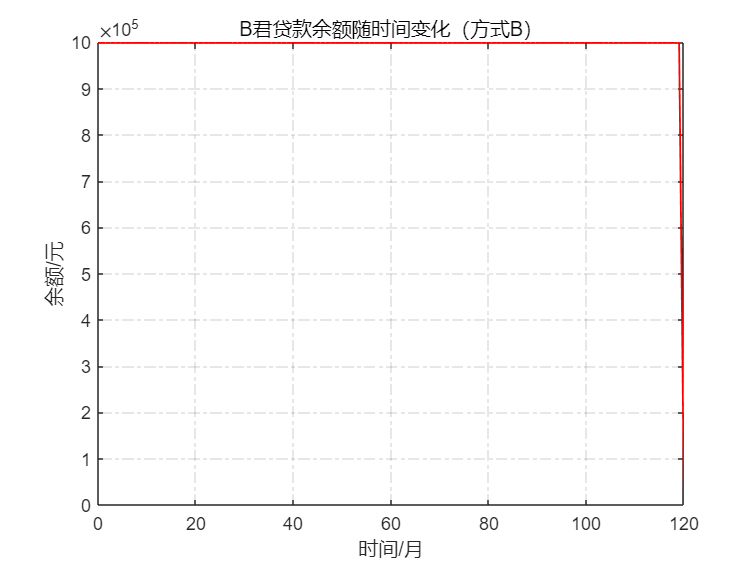

fig=plot(months, balance,'r-');
% 设置线宽
fig(1).LineWidth =1.0;
% 打开网格
grid on;
set(gca, 'XGrid', 'on', 'YGrid', 'on', 'GridLineStyle', '-.');
% 设置坐标轴和标题
xlabel('时间/月');
ylabel('余额/元');
title('B君贷款余额随时间变化（方式B）');

- **c）方式C：等额本息法**，按月等额度还本金和利息，银行贷款的最常见方式。

clear;
% 设定时间单位为两年为一月，则取时间单位长度为120
n = 10 * 12 ;
% 设定初始金额与利率
B0 = 1e6;
r2 = 0.0395;
r22 = r2 / 12;
% 计算每月还款额
m = r22*B0*(1+r22)^n / ((1+r22)^n - 1);
% 初始化余额数组
balance = zeros(n+1, 1);
balance(1) = B0;
% 计算余额
for i = 2:n+1
    balance(i) = balance(i-1)*(1+r22) - m; % 计算本月的余额
end

- 显示B君逐期余额情况：

months=0:1:n;
balance_str = arrayfun(@(x) sprintf('%.0f', x), balance, 'UniformOutput', false);
T = table(months', balance_str, 'VariableNames', {'月份', 'B君贷款余额（方式C）'});
disp(T);

    月份    B君贷款余额（方式C）
    ____    _________________

      0        {'1000000'}   
      1        {'993191' }   
      2        {'986359' }   
      3        {'979505' }   
      4        {'972629' }   
      5        {'965730' }   
      6        {'958808' }   
      7        {'951863' }   
      8        {'944895' }   
      9        {'937905' }   
     10        {'930891' }   
     11        {'923855' }   
     12        {'916795' }   
     13        {'909712' }   
     14        {'902606' }   
     15        {'895476' }   
     16        {'888323' }   
     17        {'881146' }   
     18        {'873946' }   
     19        {'866722' }   
     20        {'859474' }   
     21        {'852202' }   
     22        {'844907' }   
     23        {'837587' }   
     24        {'830244' }   
     25        {'822876' }   
     26        {'815484' }   
     27        {'808067' }   
     28        {'800626' }   
     29        {'793161' }   
     30        {'785671' }   
     31        {'

- 存储银行最后的收入：

P3=m*n;
save('P_fund.mat','P3','-append');

- 绘制图像呈现B君贷款余额：

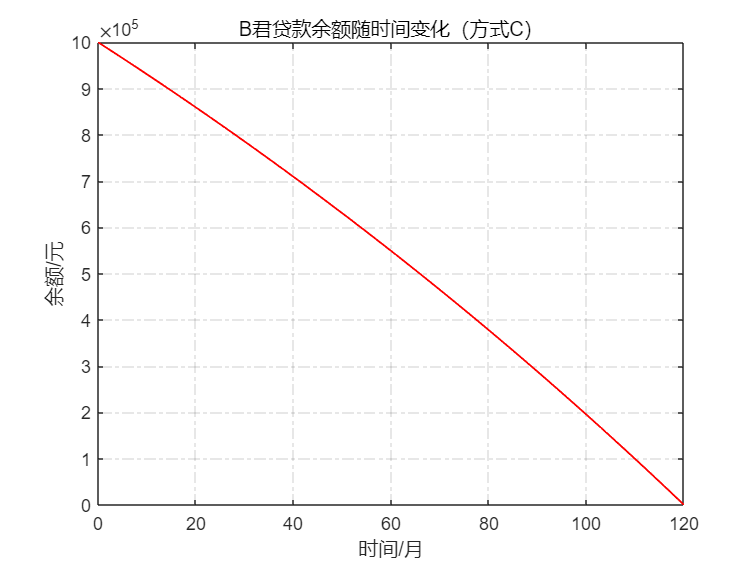

fig=plot(months, balance,'r-');
% 设置线宽
fig(1).LineWidth =1.0;
% 打开网格
grid on;
set(gca, 'XGrid', 'on', 'YGrid', 'on', 'GridLineStyle', '-.');
% 设置坐标轴和标题
xlabel('时间/月');
ylabel('余额/元');
title('B君贷款余额随时间变化（方式C）');

- **d）方式D：等额本金法**，按月等还本金，并还相应利息(利息随本金减少而减少)，银行房贷的次常见方式。

clear;
% 设定时间单位为两年为一月，则取时间单位长度为120
n=10*12;
% 设置初值，计算月利率
B0 = 1e6;
r2=0.0395;
r22 = r2 / 12;
% 每月还款额
m = B0 / n;
% 初始化余额数组
balance = zeros(n+1, 1);
interest = zeros(n, 1);
P4=0;
balance(1) = B0;
% 计算每个月的余额
for i = 2:n+1
    balance(i) = balance(i-1) - m; % 计算余额
    interest(i-1) = balance(i-1)*r22;% 计算利息
    P4=P4+interest(i-1);% 计算利息和
end

- 显示B君逐期余额情况：

months=0:1:n;
balance_str = arrayfun(@(x) sprintf('%.0f', x), balance, 'UniformOutput', false);
T = table(months', balance_str, 'VariableNames', {'月份', 'B君贷款余额（方式D）'});
disp(T);

    月份    B君贷款余额（方式D）
    ____    _________________

      0        {'1000000'}   
      1        {'991667' }   
      2        {'983333' }   
      3        {'975000' }   
      4        {'966667' }   
      5        {'958333' }   
      6        {'950000' }   
      7        {'941667' }   
      8        {'933333' }   
      9        {'925000' }   
     10        {'916667' }   
     11        {'908333' }   
     12        {'900000' }   
     13        {'891667' }   
     14        {'883333' }   
     15        {'875000' }   
     16        {'866667' }   
     17        {'858333' }   
     18        {'850000' }   
     19        {'841667' }   
     20        {'833333' }   
     21        {'825000' }   
     22        {'816667' }   
     23        {'808333' }   
     24        {'800000' }   
     25        {'791667' }   
     26        {'783333' }   
     27        {'775000' }   
     28        {'766667' }   
     29        {'758333' }   
     30        {'750000' }   
     31        {'

- 存储银行最后的收入：

% 计算还款总额
P4=P4+B0;
save('P_fund.mat','P4','-append');

- 绘制图像呈现B君贷款余额：

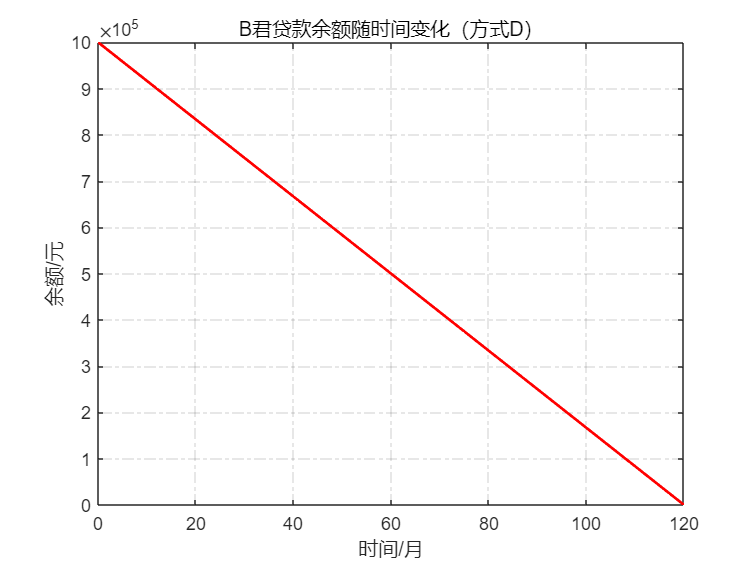

fig=plot(months, balance,'r-');
%设置线宽
fig(1).LineWidth =1.5;
%打开网格
grid on;
set(gca, 'XGrid', 'on', 'YGrid', 'on', 'GridLineStyle', '-.');
%设置坐标轴和标题
ylim([0,1e6]);
xlabel('时间/月');
ylabel('余额/元');
title('B君贷款余额随时间变化（方式D）');

- **e）方式E：借贷时先一次性扣除利息**，接下来每月还本金。

clear;
% 设置初值，计算总利息
B0 = 1e6;
r22 = 0.0395 *10;
interest=B0*r22;%扣除利息
% 设定时间单位为两年为一月，则取时间单位长度为120
n=10*12;
% 初始化余额数组
balance = zeros(n+1, 1);
P4=0;
balance(1) =B0-interest;
% 计算每月还款额
m=balance(1)/n;
% 计算每个月的余额
for i = 2:n+1
    balance(i) = balance(i-1) - m;
end

- 显示B君逐期余额情况：

months=0:1:n;
balance_str = arrayfun(@(x) sprintf('%.0f', x), balance, 'UniformOutput', false);
T = table(months', balance_str, 'VariableNames', {'月份', 'B君贷款余额（方式E）'});
disp(T);

    月份    B君贷款余额（方式E）
    ____    _________________

      0        {'605000'}    
      1        {'599958'}    
      2        {'594917'}    
      3        {'589875'}    
      4        {'584833'}    
      5        {'579792'}    
      6        {'574750'}    
      7        {'569708'}    
      8        {'564667'}    
      9        {'559625'}    
     10        {'554583'}    
     11        {'549542'}    
     12        {'544500'}    
     13        {'539458'}    
     14        {'534417'}    
     15        {'529375'}    
     16        {'524333'}    
     17        {'519292'}    
     18        {'514250'}    
     19        {'509208'}    
     20        {'504167'}    
     21        {'499125'}    
     22        {'494083'}    
     23        {'489042'}    
     24        {'484000'}    
     25        {'478958'}    
     26        {'473917'}    
     27        {'468875'}    
     28        {'463833'}    
     29        {'458792'}    
     30        {'453750'}    
     31        {'

- 存储银行最后的收入：

% 计算实际借贷额度
P5=balance(1);
save('P_fund.mat','P5','-append');

- 绘制图像呈现B君贷款余额：

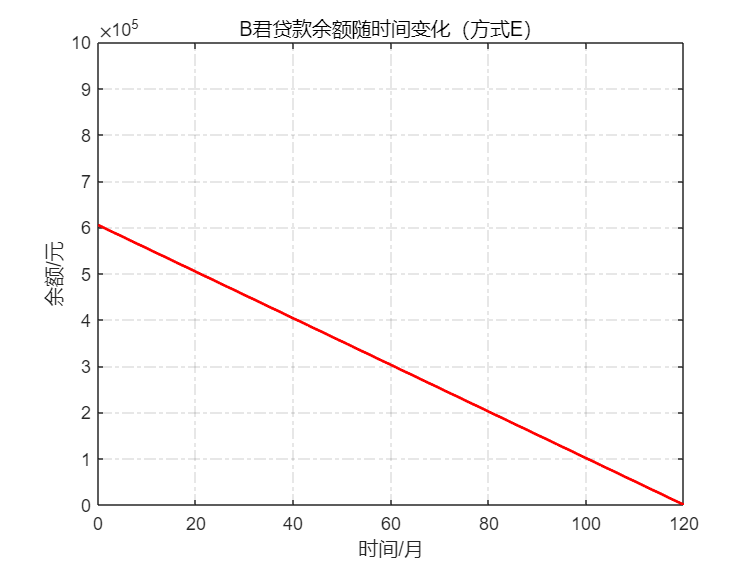

fig=plot(months, balance,'r-');
%设置线宽
fig(1).LineWidth =1.5;
%打开网格
grid on;
set(gca, 'XGrid', 'on', 'YGrid', 'on', 'GridLineStyle', '-.');
%设置坐标轴和标题
ylim([0,1e6]);
xlabel('时间/月');
ylabel('余额/元');
title('B君贷款余额随时间变化（方式E）');

#### (3)根据以上模型，比较 A-E 5 种情况下，存贷款的实际利率。

- 计算实际利率：（请将目录设置成EXP4）

clear;
% 读取各方式下实际还款总额
load('P_fund.mat');
B0=1e6;
R=zeros(5,1);
R(1)=((P1-B0)/B0)/10;% 计算方式A的实际利率
R(2)=((P2-B0)/B0)/10;% 计算方式B的实际利率
R(3)=((P3-B0)/B0)/10;% 计算方式C的实际利率
R(4)=((P4-B0)/B0)/10;% 计算方式D的实际利率
R(5)=((B0-P5)/P5)/10;% 计算方式E的实际利率
% 显示
R_str = arrayfun(@(x) sprintf('%.4f%%', x), R*100, 'UniformOutput', false);
T = table(['方式A';'方式B';'方式C';'方式D';'方式E'], R_str, 'VariableNames', {'信贷方式', '实际利率'});
disp(T);

    信贷方式      实际利率  
    _______    ___________

     方式A     {'3.9500%'}
     方式B     {'3.9500%'}
     方式C     {'2.1209%'}
     方式D     {'1.9915%'}
     方式E     {'6.5289%'}



- 经过比较可得实际利率：方式E>方式A（名义利率）=方式B>方式C>方式D。

#### (4)讨论银行盈亏情况。

- 计算银行利润：（请将目录设置成EXP4）

clear;
% 读取各方式下银行的收入和支出
load('P_fund.mat');
B0=1e6;
profit=zeros(5,1);
profit(1)=P1-PA;% 计算方式A的银行利润
profit(2)=P2-PA;% 计算方式B的银行利润
profit(3)=P3-PA;% 计算方式C的银行利润
profit(4)=P4-PA;% 计算方式D的银行利润
profit(5)=2*B0-P5-PA;% 计算方式E的银行利润
% 不同方式的盈亏
profit_str = arrayfun(@(x) sprintf('%.0f', x), profit, 'UniformOutput', false);
T = table(['方式A';'方式B';'方式C';'方式D';'方式E'], profit_str, 'VariableNames', {'信贷方式', '银行利润'});
disp(T);

    信贷方式     银行利润  
    _______    __________

     方式A     {'201565'}
     方式B     {'201565'}
     方式C     {'18657' }
     方式D     {'5711'  }
     方式E     {'201565'}



- 经过比较可得银行利润：方式A=方式B=方式E>方式C>方式D，且5种方式下银行均不会出现亏损。

#### （5）如果利率允许波动(如LPR)，做合理假设，重新考虑以上问题。

- 假设利率波动为正态随机波动，则信贷方式中方式C无法执行，方式A,E结果一样，只有方式B,D会有所不同。现计算波动的利率：

clear;
% 设定时间单位为两年为一月，则取时间单位长度为120
n=10*12;
mu = 0.0395;
sigma = 0.01;
% 生成标准正态分布的随机波动
standard_normal=zeros(n,1);
r2 = zeros(n, 1);
for i=1:n
    while(1)
        standard_normal(i) = randn;
        r2(i) = mu + sigma * standard_normal(i);
        if(r2(i)>0&&r2(i)<mu*2)
            break;
        end
    end
end
% 储存正态随机波动的年利率
save('RandomChange_r2.mat','r2');

- **方式B：先按月还息，到期还本，**实际利率接近A的利率，是信用贷款常用的做法。

clear;
% 设定时间单位为两年为一月，则取时间单位长度为120
n=10*12;
% 读取随机波动的利率
load('RandomChange_r2.mat');
% 设置初值，计算月利息
B0 = 1e6;
r22 = r2 ./12;
interest = zeros(n, 1);
% 计算账户余额
balance = zeros(n+1, 1)+B0;
balance(end)=0;
% 显示
months=0:1:n;
balance_str = arrayfun(@(x) sprintf('%.0f', x), balance, 'UniformOutput', false);
T = table(months', balance_str, 'VariableNames', {'年份', 'B君贷款余额'});
disp(T);

    年份    B君贷款余额 
    ____    ___________

      0     {'1000000'}
      1     {'1000000'}
      2     {'1000000'}
      3     {'1000000'}
      4     {'1000000'}
      5     {'1000000'}
      6     {'1000000'}
      7     {'1000000'}
      8     {'1000000'}
      9     {'1000000'}
     10     {'1000000'}
     11     {'1000000'}
     12     {'1000000'}
     13     {'1000000'}
     14     {'1000000'}
     15     {'1000000'}
     16     {'1000000'}
     17     {'1000000'}
     18     {'1000000'}
     19     {'1000000'}
     20     {'1000000'}
     21     {'1000000'}
     22     {'1000000'}
     23     {'1000000'}
     24     {'1000000'}
     25     {'1000000'}
     26     {'1000000'}
     27     {'1000000'}
     28     {'1000000'}
     29     {'1000000'}
     30     {'1000000'}
     31     {'1000000'}
     32     {'1000000'}
     33     {'1000000'}
     34     {'1000000'}
     35     {'1000000'}
     36     {'1000000'}
     37     {'1000000'}
     38     {'1000000'}
     39     {'1000000

- 存储银行最后的收入：

p2=0;
for i=1:n
    interest(i)=B0*r22(i);
    p2=p2+interest(i);
end
p2=balance(1)+p2;
save('P_fund.mat','p2','-append');

- 绘制图像呈现B君贷款余额：

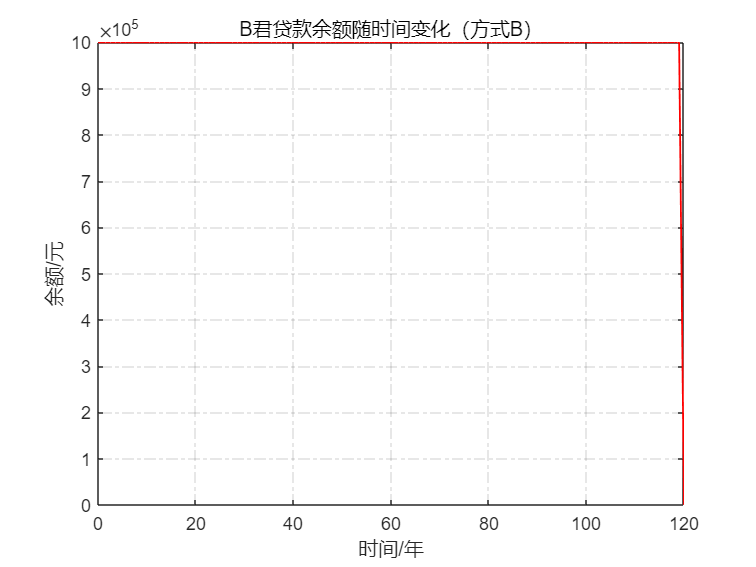

fig=plot(months, balance,'r-');
% 设置线宽
fig(1).LineWidth =1.0;
% 打开网格
grid on;
set(gca, 'XGrid', 'on', 'YGrid', 'on', 'GridLineStyle', '-.');
% 设置坐标轴和标题
xlabel('时间/年');
ylabel('余额/元');
title('B君贷款余额随时间变化（方式B）');

- 方式D：**等额本金法**，按月等还本金，并还相应利息(利息随本金减少而减少)，银行房贷的次常见方式。

clear;
% 设定时间单位为两年为一月，则取时间单位长度为120
n=10*12;
% 读取随机波动的利率
load('RandomChange_r2.mat');
% 设置初值，计算月利率
B0 = 1e6;
r22 = r2 ./ 12;
% 每月还款额
m = B0 / n;
% 初始化余额数组
balance = zeros(n+1, 1);
interest = zeros(n, 1);
p4=0;
balance(1) = B0;
% 计算每个月的余额
for i = 1:n
    balance(i+1) = balance(i) - m; % 计算余额
    interest(i) = balance(i)*r22(i);% 计算利息
    p4=p4+interest(i);% 计算利息和
end
% 显示
months=0:1:n;
balance_str = arrayfun(@(x) sprintf('%.0f', x), balance, 'UniformOutput', false);
T = table(months', balance_str, 'VariableNames', {'月份', 'B君贷款余额'});
disp(T);

    月份    B君贷款余额 
    ____    ___________

      0     {'1000000'}
      1     {'991667' }
      2     {'983333' }
      3     {'975000' }
      4     {'966667' }
      5     {'958333' }
      6     {'950000' }
      7     {'941667' }
      8     {'933333' }
      9     {'925000' }
     10     {'916667' }
     11     {'908333' }
     12     {'900000' }
     13     {'891667' }
     14     {'883333' }
     15     {'875000' }
     16     {'866667' }
     17     {'858333' }
     18     {'850000' }
     19     {'841667' }
     20     {'833333' }
     21     {'825000' }
     22     {'816667' }
     23     {'808333' }
     24     {'800000' }
     25     {'791667' }
     26     {'783333' }
     27     {'775000' }
     28     {'766667' }
     29     {'758333' }
     30     {'750000' }
     31     {'741667' }
     32     {'733333' }
     33     {'725000' }
     34     {'716667' }
     35     {'708333' }
     36     {'700000' }
     37     {'691667' }
     38     {'683333' }
     39     {'675000'

- 存储银行最后的收入：

% 计算还款总额
p4=p4+B0;
save('P_fund.mat','p4','-append');

- 绘制图像呈现B君贷款余额：

fig=plot(months, balance,'r-');
%设置线宽
fig(1).LineWidth =1.5;
%打开网格
grid on;
set(gca, 'XGrid', 'on', 'YGrid', 'on', 'GridLineStyle', '-.');
%设置坐标轴和标题
ylim([0,1e6]);
xlabel('时间/月');
ylabel('余额/元');
title('B君贷款余额随时间变化（方式D）');

- 根据以上模型，比较了 A,B,D,E 4 种情况下，存贷款的实际利率：（请将目录设置成EXP4）

clear;
% 读取各方式下实际还款总额
load('P_fund.mat');
B0=1e6;
R=zeros(4,1);
R(1)=((P1-B0)/B0)/10;% 计算方式A的实际利率
R(2)=((p2-B0)/B0)/10;% 计算方式B的实际利率
R(3)=((p4-B0)/B0)/10;% 计算方式D的实际利率
R(4)=((B0-P5)/P5)/10;% 计算方式E的实际利率
% 显示
R_str = arrayfun(@(x) sprintf('%.4f%%', x), R*100, 'UniformOutput', false);
T = table(['方式A';'方式B';'方式D';'方式E'], R_str, 'VariableNames', {'信贷方式', '实际利率'});
disp(T);

    信贷方式      实际利率  
    _______    ___________

     方式A     {'3.9500%'}
     方式B     {'3.9221%'}
     方式D     {'2.0205%'}
     方式E     {'6.5289%'}



- 经过比较可得实际利率：方式E>方式A（名义利率）>方式B>方式D，而方式B与名义利率（0.0395）接近。

- 讨论银行盈亏：（请将目录设置成EXP4）

clear;
% 读取各方式下银行的收入和支出
load('P_fund.mat');
profit=zeros(4,1);
B0=1e6;
profit(1)=P1-PA;% 计算方式A的银行利润
profit(2)=p2-PA;% 计算方式B的银行利润
profit(3)=p4-PA;% 计算方式D的银行利润
profit(4)=2*B0-P5-PA;% 计算方式E的银行利润
% 不同方式的盈亏
profit_str = arrayfun(@(x) sprintf('%.0f', x), profit, 'UniformOutput', false);
T = table(['方式A';'方式B';'方式D';'方式E'], profit_str, 'VariableNames', {'信贷方式', '银行利润'});
disp(T);

    信贷方式     银行利润  
    _______    __________

     方式A     {'201565'}
     方式B     {'198773'}
     方式D     {'8613'  }
     方式E     {'201565'}



- 经过比较可得银行利润：方式A=方式E>方式D，而方式B与方式A接近；且4种方式下银行均（绝大概率）不会出现亏损。

#### 2. 草场放牧    

    研究将鹿群放入草场后草和鹿两种群的相互作用。草的生长遵从 Logistic 规律，年固有增长率0.8，最大密度为3000(密度单位)，在草最茂盛时每只鹿每年可吃掉1.6(密度单位)的草。若没有草，鹿群的年死亡率高达 0.9，而草的存在可使鹿的死亡得以补偿，在草最茂盛时补偿率为1.5。作出一些简化假设，用差分方程模型描述草和鹿两种群数量的变化过程。就以下情况进行讨论：

(1) 比较将 100 只鹿放入密度为 1000 和密度为 3000 的草场两种情况。

(2)适当改变参数，观察变化趋势。

#### (1) 比较将 100 只鹿放入密度为 1000 和密度为 3000 的草场两种情况。

- 符号说明：

a:草独立生存时的自然增长率；b: 鹿群掠取草的能力；c : 鹿群独自存在时的死亡率；d: 草对鹿群的供养能力。并假设鹿食草能力与草的茂盛程度呈线性关系，草对鹿的补偿能力与草的茂盛程度呈线性关系，可以确定参数如下：

xm= 3000;%草的最大密度为3000
a = 0.8;
bb= 1.6;
b = bb/xm;
c = 0.9;
dd= 1.5;
d = dd/xm;
T = 100;   % 研究时间（年）

- 记草的密度为xk;xm=3000,满足规律为$x_{k+1}-x_k=x_k [a(1-\frac {x_k}{ x_m})-by_k] , k=0,1,\cdots$

- 记鹿群数量为yk;y0=100,满足规律为$y_{k+1}-y_{k}=y_k(-c+dx_k),k=0,1,\cdots$

- a）将 100 只鹿放入密度为 1000的草场：

%初始条件
x0 = 1000;  
y0 = 100;   
% 初始化每年的草场密度和鹿群数量
X = zeros(T+1, 1);  % Grass population
Y = zeros(T+1, 1);  % Deer population
X(1) = x0;
Y(1) = y0;

% 差分方程模型
for k = 1:T
    %草场增长密度
    dx =  X(k) * (a *(1 - X(k)/xm)-b*Y(k));
    % 鹿群增长数量
    if X(k) > 0
        dy=Y(k)*(-c+d*X(k));
    else
        dy=Y(k)*(-c);
    end
    % 更新数值
    X(k+1) = X(k) + dx ;
    Y(k+1) = Y(k) + dy;
end

- b）将 100 只鹿放入密度为 3000的草场：

%初始条件
xx0 = 3000;  % 草
yy0 = 100;   % 鹿
% 初始化每年的草场密度和鹿群数量
XX = zeros(T+1, 1);  % 草
YY = zeros(T+1, 1);  % 鹿
XX(1) = xx0;
YY(1) = yy0;
% 差分方程模型
for k = 1:T
    %草场增长密度
    dxx =  XX(k) * (a *(1 - XX(k)/xm)-b*YY(k));
    % 鹿群增长数量
    % Deer population change
    if XX(k) > 0
        dyy=YY(k)*(-c+d*XX(k));
    else
        dyy=YY(k)*(-c);
    end
    % 更新数值
    XX(k+1) = XX(k) + dxx ;
    YY(k+1) = YY(k) + dyy;
end

- c）对比图像：

- 情况一：将 100 只鹿放入密度为 1000的草场：

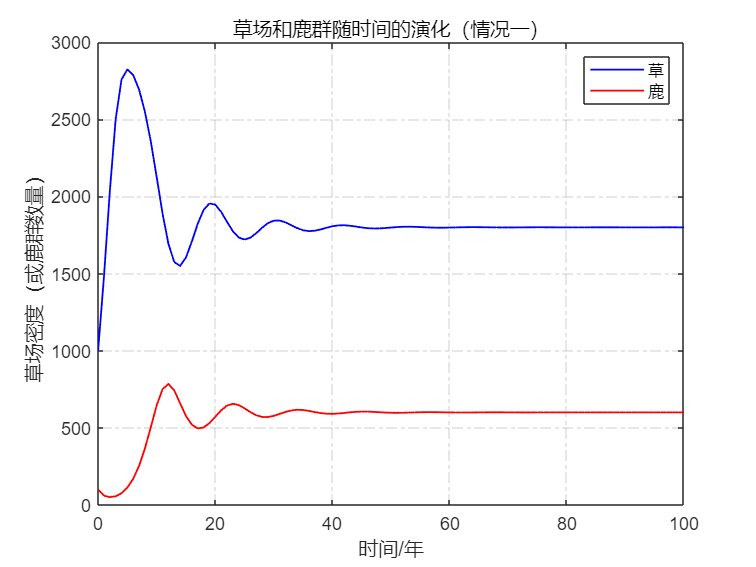

figure;
fig=plot(0:1:T, X, 'b',0:1:T, Y, 'r');
%设置线宽
fig(1).LineWidth =1.0;fig(2).LineWidth =1.0;
%打开网格
grid on;
set(gca, 'XGrid', 'on', 'YGrid', 'on', 'GridLineStyle', '-.');
%设置坐标轴和标题
xlabel('时间/年');
ylabel('草场密度（或鹿群数量）');
legend('草', '鹿');
title('草场和鹿群随时间的演化（情况一）');

- 情况二：将 100 只鹿放入密度为 3000的草场：

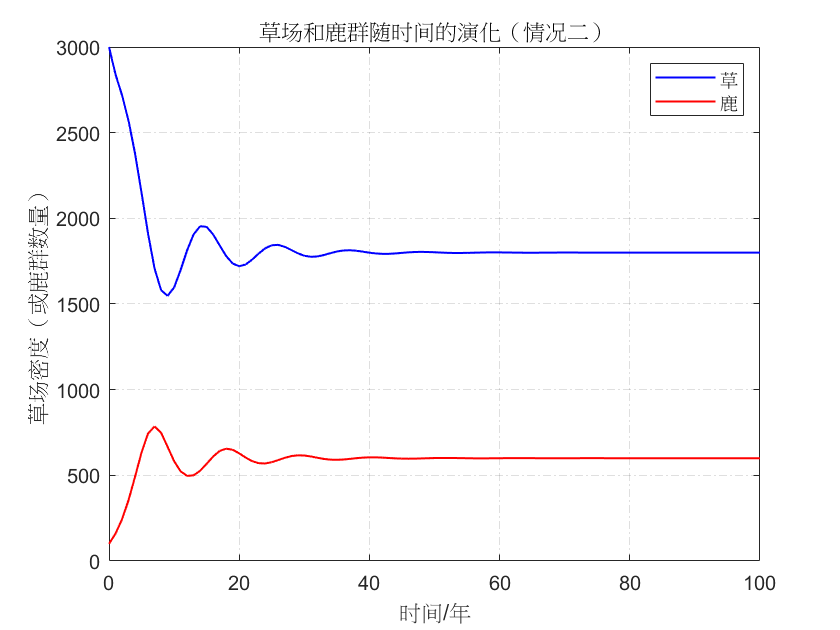

figure;
fig=plot(0:1:T, XX, 'b',0:1:T, YY, 'r');
%设置线宽
fig(1).LineWidth =1.0;fig(2).LineWidth =1.0;
%打开网格
grid on;
set(gca, 'XGrid', 'on', 'YGrid', 'on', 'GridLineStyle', '-.');
%设置坐标轴和标题
xlabel('时间/年');
ylabel('草场密度（或鹿群数量）');
legend('草', '鹿');
title('草场和鹿群随时间的演化（情况二）');

#### (2)适当改变参数，观察变化趋势。

- 调整参数：

clear;
xm = 3000;
a=0.8;
bb = 1.6;
b=bb/xm;
c = 0.9;
dd = 1.5;
x0=2000;
d=dd/xm;
T = 100;   % 研究时间（年）

- 仿真各参数下的运行结果：

%初始条件
y0 = 100;   
% 初始化每年的草场密度和鹿群数量
X = zeros(T+1, 1);  % Grass population
Y = zeros(T+1, 1);  % Deer population
X(1) = x0;
Y(1) = y0;

% 差分方程模型
for k = 1:T
    %草场增长密度
    dx =  X(k) * (a *(1 - X(k)/xm)-b*Y(k));
    % 鹿群增长数量
    if X(k) > 0
        dy=Y(k)*(-c+d*X(k));
    else
        dy=Y(k)*(-c);
    end
    % 更新数值
    X(k+1) = X(k) + dx ;
    Y(k+1) = Y(k) + dy;
end

- 分析图像：

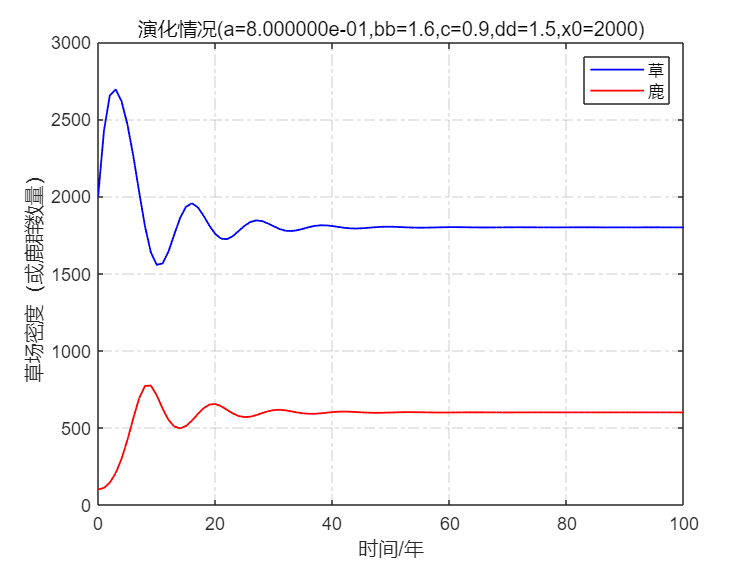

figure;
fig=plot(0:1:T, X, 'b',0:1:T, Y, 'r');
%设置线宽
fig(1).LineWidth =1.0;fig(2).LineWidth =1.0;
%打开网格
grid on;
set(gca, 'XGrid', 'on', 'YGrid', 'on', 'GridLineStyle', '-.');
%设置坐标轴和标题
xlabel('时间/年');
ylabel('草场密度（或鹿群数量）');
legend('草', '鹿');
str = sprintf('演化情况(a=%d,bb=%.1f,c=%.1f,dd=%.1f,x0=%d)', a,bb,c,dd,x0);
title(str);

- 经过对比，可以得到以下的结论：

- 调整草场初值，若草场初值为0，则鹿群在数年内死亡，草场也不会生长；若刚开始草场初值大于0，则无论其是否大于最大密度，最终草场和鹿群数量都趋于稳定，且稳定值与初值无关。

- 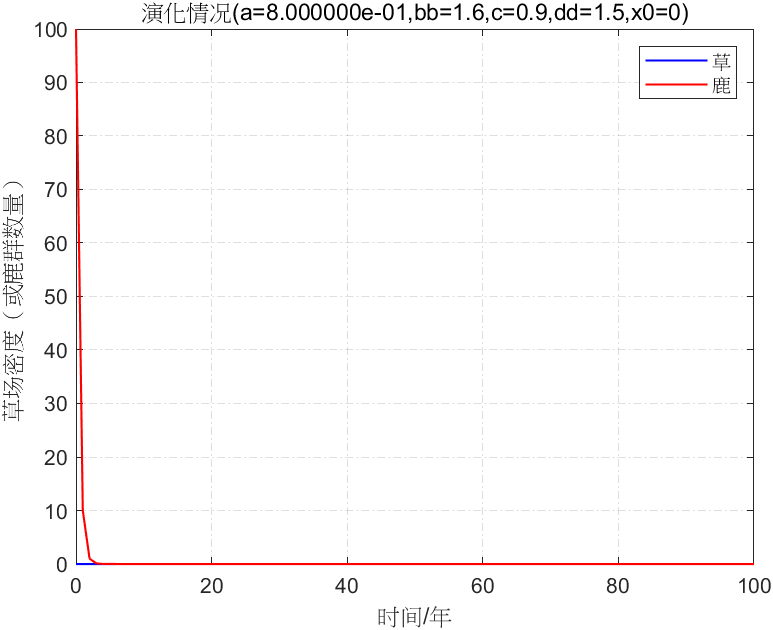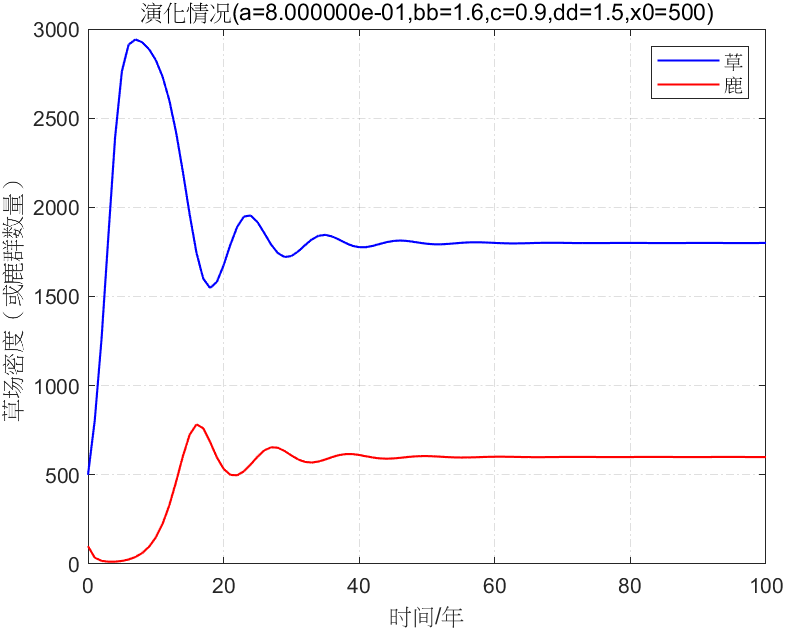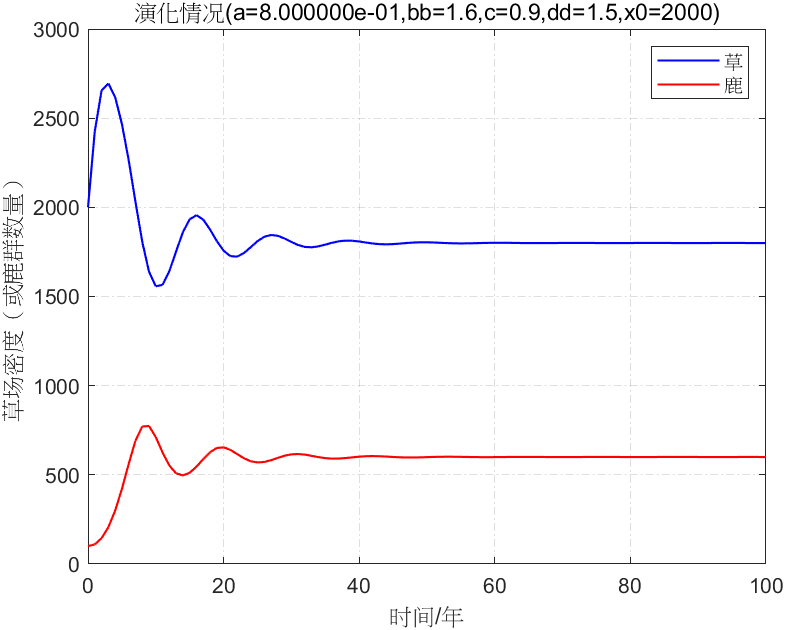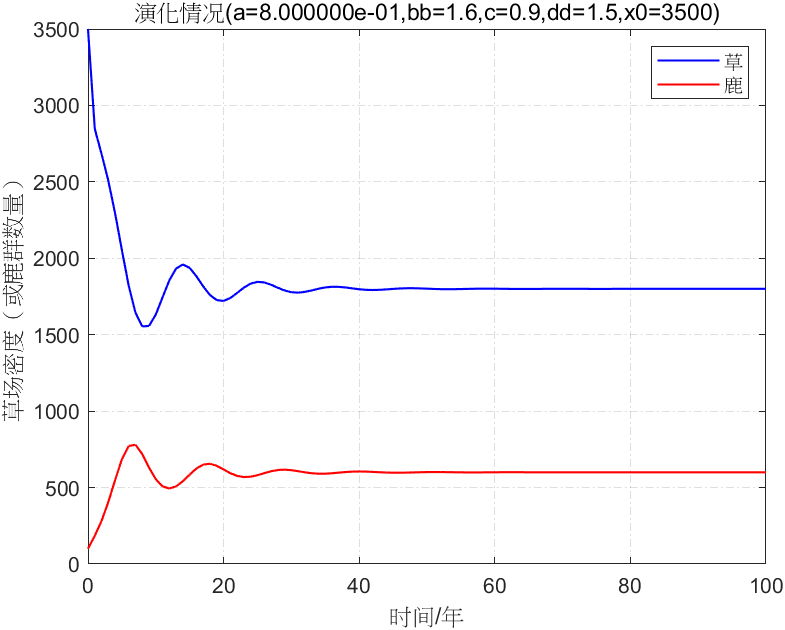

- 调整参数dd（草最茂盛时对鹿群的供养能力）,发现dd越大，则草和鹿群达到稳定数目的时间越长，且草的稳定解越小，鹿的稳定解越大。当xm*dd<=c时，发现最终鹿群会走向灭绝，符合模型假设。

- 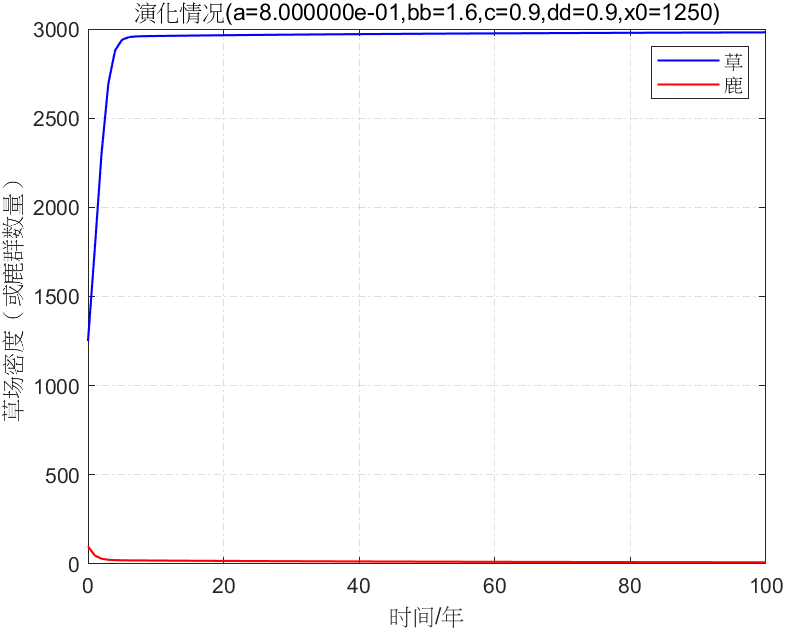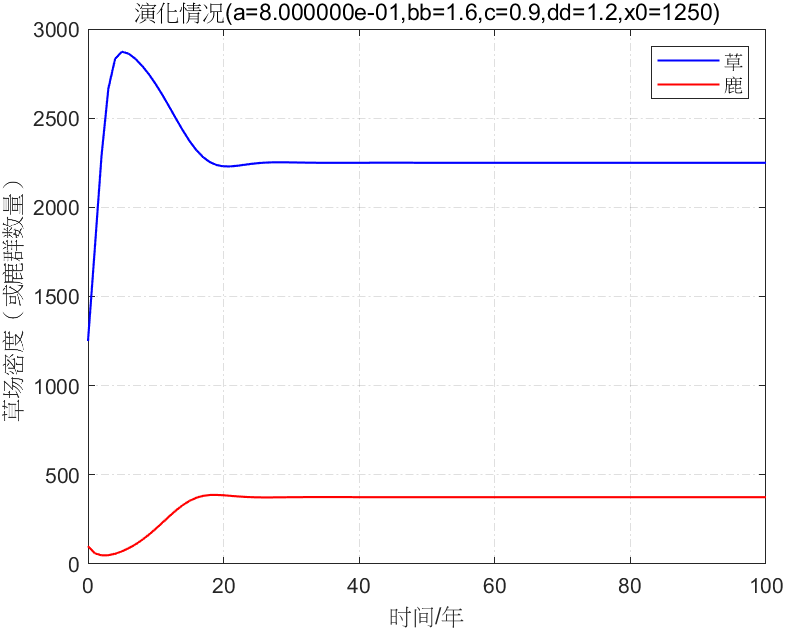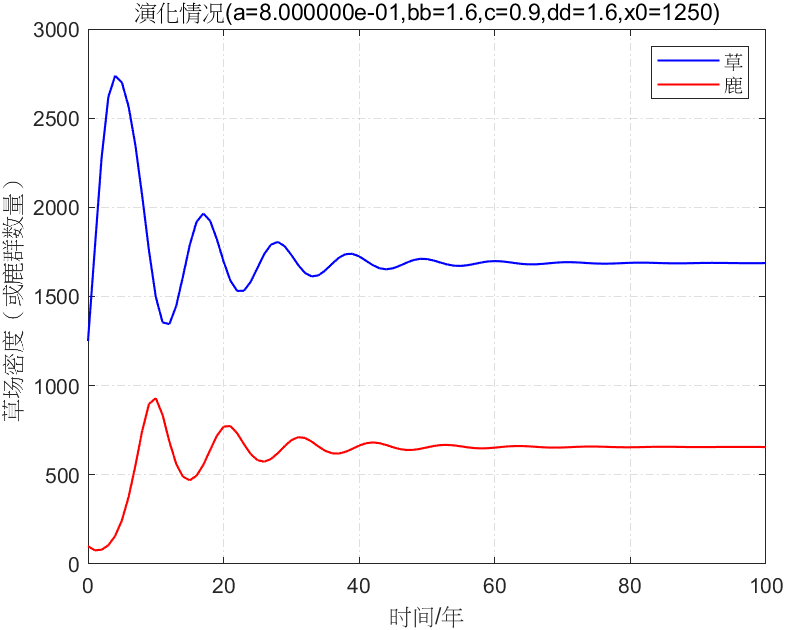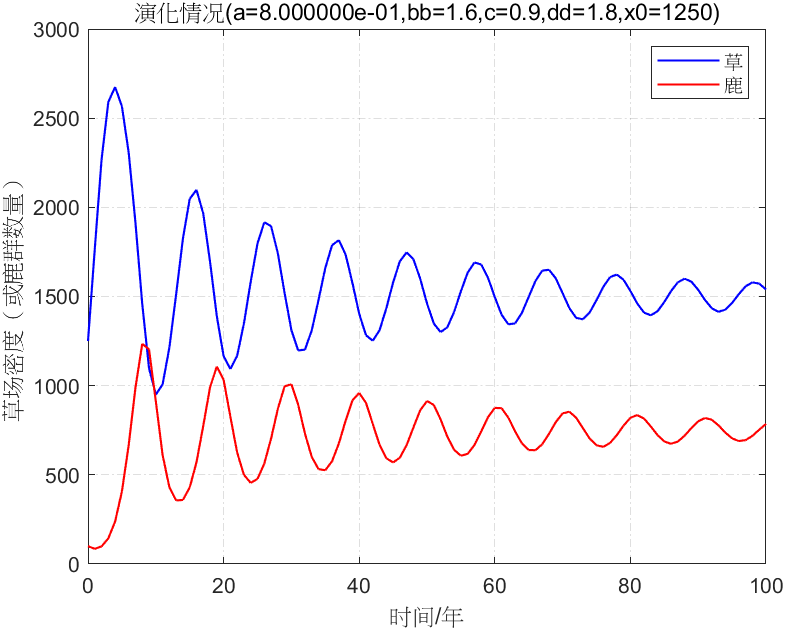

- 调整参数bb（草最茂盛时鹿群掠取草的能力），发现bb越小，则草和鹿群达到稳定数目的时间越长，且草的稳定解越小，鹿的稳定解越大。在bb<1时，甚至会出现鹿群数量大于草的情况。

- 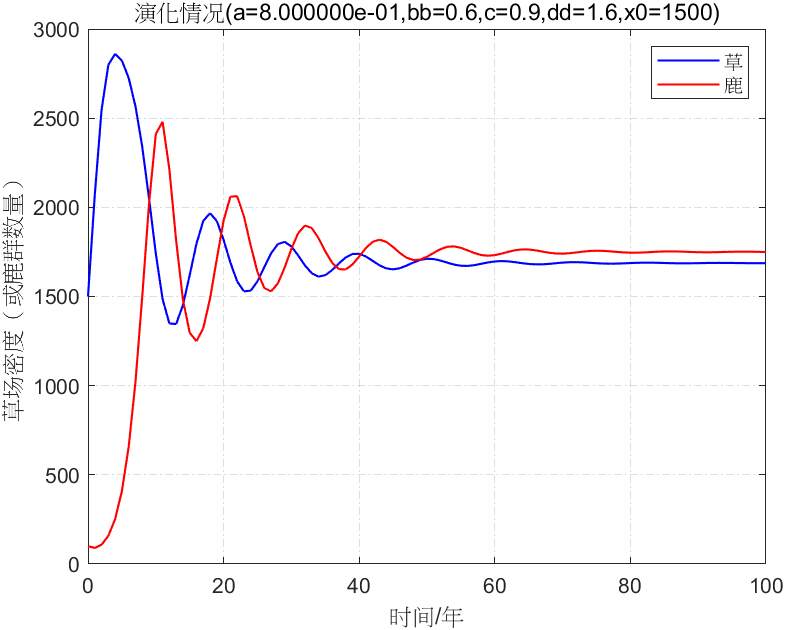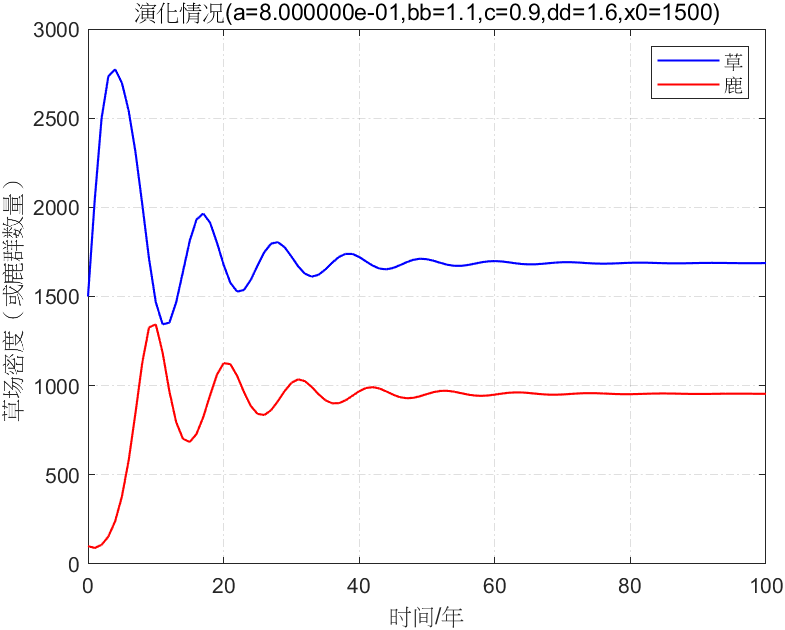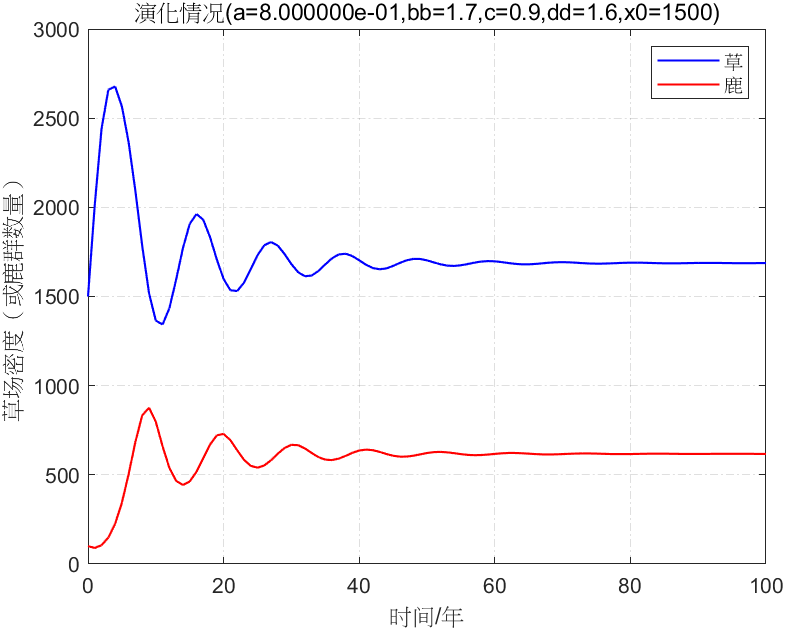

- 调整参数a（草独立存在时的增长率）和c（鹿群独立存在时的死亡率），发现当c较小或a较大时，则草和鹿群达成稳定所需时间非常长，所以近似出现周期现象，近似于Volterra模型。

-